addpath C:\Users\ivans\OneDrive\Documents\GitHub\saccade\edf-converter
demo=Edf2Mat('TWH175Demo280322-1537.edf');

eye_track = struct(demo);
save("eye_track.mat",'eye_track');

timeline = eye_track.timeline;
posX = int64(eye_track.Samples.posX); posY = int64(eye_track.Samples.posY);

coord_all = [966.500000000000	862.799987792969	835.299987792969	168.600006103516];

coord_start = int64([coord_all(1)	coord_all(2)]); %start (x,y) coordinates from a random saccade
coord_end = int64([coord_all(3)	coord_all(4)]); %end (x,y) coordinates from a random saccade

count=1;
for i = 1:numel(posX)
    if coord_start(1) == posX(i) & coord_start(2) == posY(i)
        start_ind(count) = i; count=count+1;
    end
end

count=1;
for i = 1:numel(posX)
    if coord_end(1) == posX(i) & coord_end(2) == posY(i)
        end_ind(count) = i; count=count+1;
    end
end

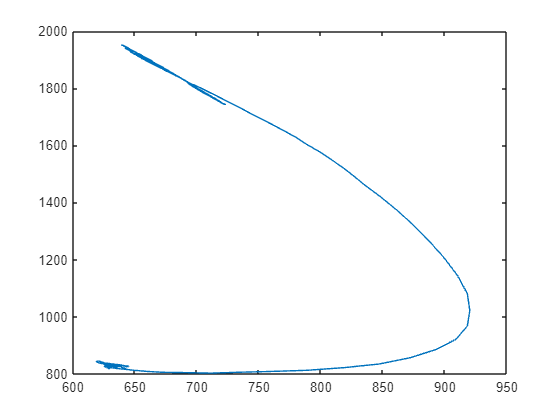

%basically, find the posX and posY indices that correspond to one of the
%known saccade start and end x,y coordinates in Marco's table. next, find
%the unix timestamp in the table associated with each. that time should
%correspond with the timestamp in EDF.

for i = 1:numel(start_ind)

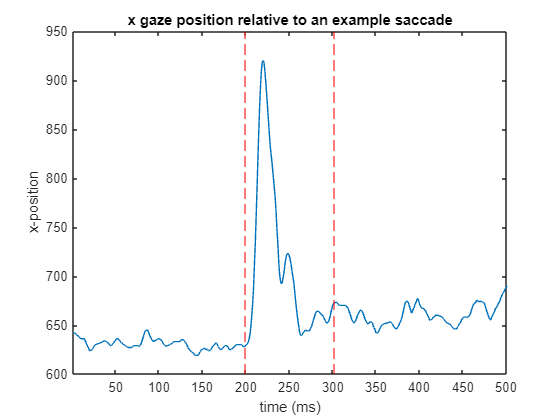

    for j = 1:numel(end_ind)
        diff_ts(i,j) = end_ind(j)-start_ind(i);
    end
end


%min_diff = min(min(abs(diff_ts)));

%figure;imagesc(abs(diff_ts))
%now check if this difference corresponds with corresponding saccade duration
%if so, the unix timestamp corresponding to saccade start corresponds to 

unix_timestamps = [1648482139.53120	1648482139.60020];

start_ts_unix_ms = int64(round(unix_timestamps(1)*1000));

end_ts_unix_ms = int64(round(unix_timestamps(2)*1000));

%the difference that corresponds to saccade duration is diff_ts(1,1)
start_ind_verified = start_ind(1); end_ind_verified = end_ind(1); %the indices depend on the diff_ts indices of the element
%that is closest to saccade duration from Marco's table

timestamp_start_sacc = timeline(start_ind_verified);
timestamp_end_sacc = timeline(end_ind_verified);

%timestamps_start_sacc corresponds to start_ts_unix_ms
%calculate the difference between timestamps_start_sacc and the first EDF
%timestamps

start_sacc_start_rec_diff = timestamp_start_sacc - timeline(1);

first_ts_edf_converted_to_unix_ms = start_ts_unix_ms - start_sacc_start_rec_diff;

save('first_ts_edf_converted_to_unix_ms', 'first_ts_edf_converted_to_unix_ms')

sampling_rate = eye_track.RawEdf.RECORDINGS.sample_rate;

num_ts = numel(eye_track.Samples.time*(sampling_rate/1000));

first_ts_edf_converted_to_unix_ms = int64(first_ts_edf_converted_to_unix_ms);
 
eye_track.Samples.first_ts_edf_converted_to_unix_ms = first_ts_edf_converted_to_unix_ms;

eye_track_timeline_unix_ms = first_ts_edf_converted_to_unix_ms:1:(first_ts_edf_converted_to_unix_ms+num_ts);

eye_track.Samples.eye_track_timeline_unix_ms = eye_track_timeline_unix_ms;

save('eye_track','eye_track');

clearvars -EXCEPT saccade;



figure;plot(posX((start_ind_verified-200):(end_ind_verified+200)),posY((start_ind_verified-200):(end_ind_verified+200)))

figure;plot(posX((start_ind_verified-200):(end_ind_verified+200)));title('x gaze position relative to an example saccade');
xline(200,'r--'); xline((numel((start_ind_verified-200):(end_ind_verified+200))-200),'r--'); 
xlim([1 diff([start_ind_verified,end_ind_verified]) + 400]);xlabel('time (ms)');ylabel('x-position')